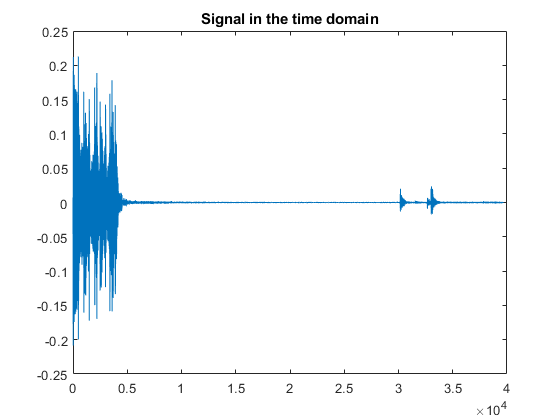

load short_modem_rx.mat

% The received signal includes a bunch of samples from before the
% transmission started so we need discard the samples from before
% the transmission started. 

start_idx = find_start_of_signal(y_r,x_sync);
% start_idx now contains the location in y_r where x_sync begins
% we need to offset by the length of x_sync to only include the signal
% we are interested in
y_t = y_r(start_idx+length(x_sync):end); % y_t is the signal which starts at the beginning of the transmission


figure
plot(y_t)
title("Signal in the time domain")

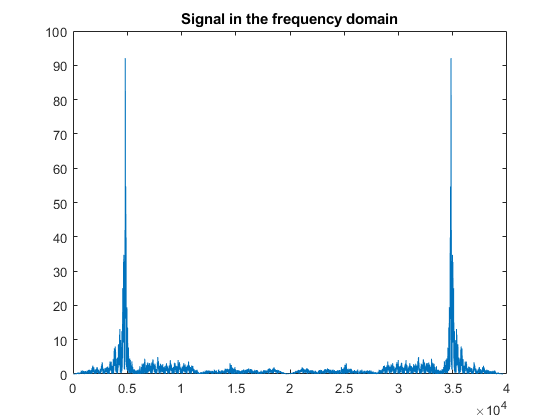


figure
plot(abs(fft(y_t)))
title("Signal in the frequency domain")

## Put your decoder code here

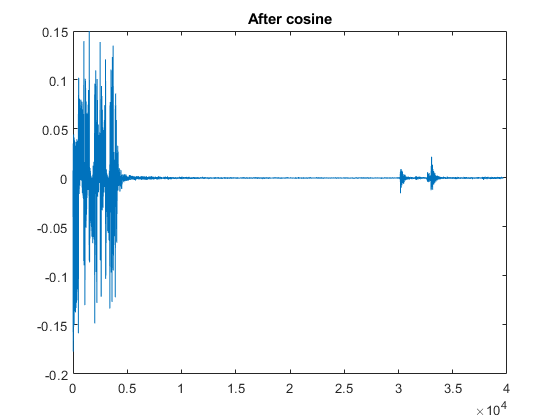

% Setting up cosine

SymbolPeriod = 100;
f_c = 1000;
c = cos(2*pi*f_c/Fs*[0:length(y_t)-1]');

y_conv = y_t.*c;

% Check the signal

figure
plot(y_conv)
title("After cosine")

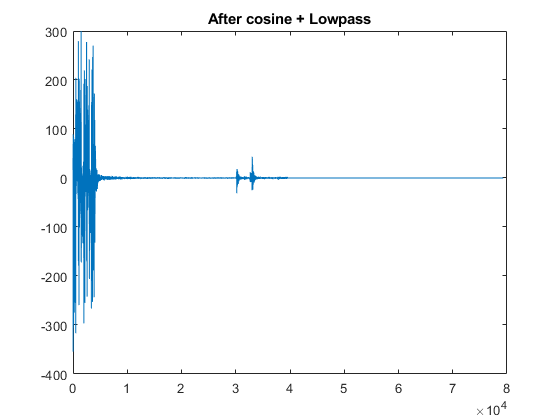


% Set up lowpass filter

Fs = 8192;   % set the sampling frequency
W = 2*pi*f_c;% set the cutoff frequency to 2 * pi * 100 rads/s
t = [0:length(y_t)-1]*(1/f_c);   % create a 200 sample time vector to generate sinc
h = W/pi*sinc(W/pi*t);   % this is the impulse response

% y_convnew = fft(y_conv);

y_final = conv(y_conv, h);

% Check the signal

figure
plot(y_final)
title("After cosine + Lowpass")

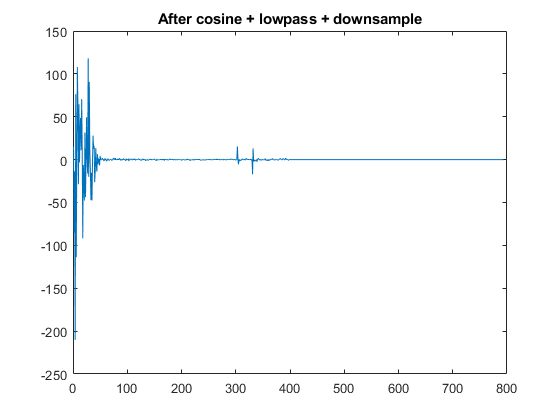


% Downsample

y_ds = downsample(y_final, SymbolPeriod);

% Check signal

figure
plot(y_ds)
title("After cosine + lowpass + downsample")

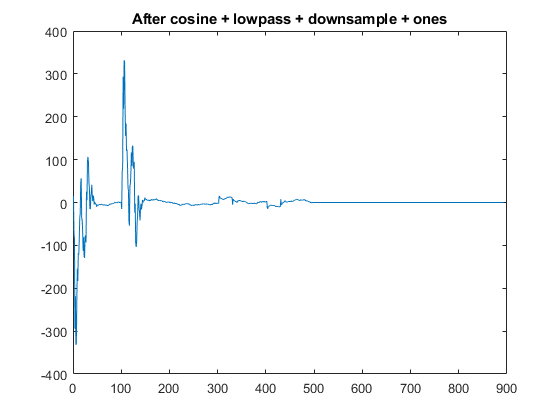



% May not need stuff after this
y_boxy = conv(y_ds, ones(SymbolPeriod, 1));

plot(y_boxy)
title("After cosine + lowpass + downsample + ones")


% y_decode = BitsToString(y_ds)

Error using reshape
Size arguments must be real integers.

Error in BitsToString (line 8)
binary_chars = reshape(binary, sz_binary/8, 8);


% convert to a string assuming that x_d is a vector of 1s and 0s
% representing the decoded bits